Example 7.8

The** symmetric angle-ply laminate** described in Example 7.4 is subjected to a single uniaxial force per unit length Nx = 50 MPamm. Determine the resulting stresses associated with the x and y axes in each lamina..

Example 7.4 Determine the stiffness matrix for a [+45/−45/−45+45] symmetric angle-ply laminate

consisting of 0.25 mm-thick unidirectional AS/3501 carbon/epoxy laminae.

An exploded view of the laminate is shown in Figure 7.15.Exploded view of [+45/−45/−45/+45] symmetric laminate.

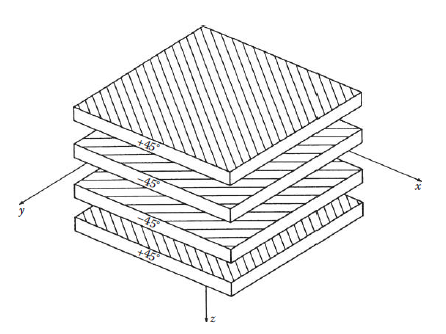

% for
clc
clear all
close all

%From Table 2.2, the lamina engineering constants are
r = 2000 % in mm

r = 2000

P = 0.8; % in Mpa
t = 0.25; % in mm thickness of each lamina
fprintf('r=%d mm, P=%d Mpa , t=%d mm, ',r,P,t)

r=2000 mm, P=8.000000e-01 Mpa , t=2.500000e-01 mm, 


$$E_1 =33\;\textrm{Gpa}\;,\;E_2 =33\;\textrm{Gpa}\;,G_{12} =4\;\textrm{Gpa}\;,\;\;\nu_{12} =0\ldotp 33\;,\nu_{21} =0\ldotp 44\;\;$$


E1 = 138; % in Gpa
E2 = 9;
G12 = 6.9;  %Gpa
v12 = 0.3;
v21 = E2*v12/E1;


$$X_t =33\;\textrm{Mpa}\;,X_c =55\;\textrm{Mpa}\;\;,Y_t =44\;\textrm{Mpa}\;\;,Y_c =99\;\textrm{Mpa}\;,\;S=44\;\textrm{Mpa}$$


Xt = 1500 ;% in Mpa
Xc = Xt;
Yt = 40;
Yc = 246;
S = 68;
% symstr = ["'The equation of motion is'"; "m*diff(y,t,t) == m*g-k*y";"'where k is the elastic coefficient.'"];
% displayFormula(symstr)

Substitution of the above engineering constants in Equations 2.27 yields the components of the **lamina stiffness matrix** associated with the principal material axes: for quasi-isotropic or **Specially Orthotropic Lamina :**

 $Q_{\textrm{ij}}$=$
$\left[\begin{array}{ccc}Q_{11} & Q_{12} & 0 \\ Q_{21} & Q_{22} & 0 \\ 0 & 0 & 2 Q_{66}\end{array}\right]$$


$$
$$
\begin{array}{l}
Q_{11}=\frac{S_{22}}{S_{11} S_{22}-S_{12}^{2}}=\frac{E_{1}}{1-v_{12} v_{21}} \\

\end{array}
$$$$

$$=\frac{33}{1-33}=55\;\textrm{Mpa}$$



$$
$$
\begin{array}{l}Q_{21}=

Q_{12}=-\frac{S_{12}}{S_{11} S_{22}-S_{12}^{2}}=\frac{v_{12} E_{2}}{1-v_{12} v_{21}}=
\end{array}
$$$$

$$\frac{333}{1-444}=444\;\textrm{Mpa}$$


$
$$
\begin{array}{l} Q_{22}=\frac{S_{11}}{S_{11} S_{22}-S_{12}^{2}}=\frac{E_{2}}{1-v_{12} v_{21}} 
\end{array}
$$$=$\frac{22}{1-33*33}=55\;\textrm{Mpa}$

$
$$
\begin{array}{l}
Q_{66}=\frac{1}{S_{66}}=G_{12}
\end{array}
$$$=444 Mpa

[Q]=


Q11 = E1/(1-v12*v21) %

Q11 = 138.8148

Q12 = v12*E2/(1-v12*v21)

Q12 = 2.7159

Q21 = Q12

Q21 = 2.7159

Q22 =E2/(1-v12*v21)

Q22 = 9.0531

Q66 = G12

Q66 = 6.9000

Q26 = 0 ;Q16 = Q26; % assuming  lamina
Q = [Q11 Q12 Q16; Q21 Q22 Q26 ; Q16 Q26 Q66]

Q =   138.8148    2.7159         0
    2.7159    9.0531         0
         0         0    6.9000


vpa(Q,4)

$$ans = \left(\begin{array}{ccc} 138.8 & 2.716 & 0\\ 2.716 & 9.053 & 0\\ 0 & 0 & 6.9 \end{array}\right)$$

Stacking sequence,  ${\theta =\left\lbrack 3\;,45,\;\;5,\;\;6\;\right\rbrack }_S$


theta = [45 -45 -45 45]   % hypothetical stacking of ( in degree

theta =     45   -45   -45    45


N = length(theta); % total number of laminae
fprintf('Total number of lamina = %d',N)

Total number of lamina = 4

fprintf('Distance of each surface of lamina from mid plane in mm')

Distance of each surface of lamina from mid plane in mm

z = t*(-length(theta)/2:length(theta)/2) % 

z =    -0.5000   -0.2500         0    0.2500    0.5000



A = zeros([3 3]); % initialization
B = A;
D = A;

The elements **transformed lamina stiffness matrix,** $\bar{Q_{\textrm{ij}} }$ for each lamina can be found by using given formula:  $\bar{Q_{\textrm{ij}} } =$ $
$$
\left[\begin{array}{ccc}
\bar{Q}_{11} & \bar{Q}_{12} & \bar{Q}_{16} \\
\bar{Q}_{12} & \bar{Q}_{22} & \bar{Q}_{26} \\
\bar{Q}_{16} & \bar{Q}_{26} & \bar{Q}_{66}
\end{array}\right]
$$$


$$$$
\begin{array}{l}
\bar{Q}_{11}=Q_{11} \mathrm{c}^{4}+Q_{22} \mathrm{~s}^{4}+2\left(Q_{12}+2 Q_{66}\right) \mathrm{s}^{2} \mathrm{c}^{2} \\
\bar{Q}_{12}=\left(Q_{11}+Q_{22}-4 Q_{66}\right) \mathrm{s}^{2} \mathrm{c}^{2}+Q_{12}\left(\mathrm{c}^{4}+\mathrm{s}^{4}\right) \\
\bar{Q}_{22}=Q_{11} \mathrm{~s}^{4}+Q_{22} \mathrm{c}^{4}+2\left(Q_{12}+2 Q_{66}\right) \mathrm{s}^{2} \mathrm{c}^{2} \\
\bar{Q}_{16}=\left(Q_{11}-Q_{12}-2 Q_{66}\right) \mathrm{c}^{3} \mathrm{~s}-\left(Q_{22}-Q_{12}-2 Q_{66}\right) \mathrm{cs}^{3} \\
\bar{Q}_{26}=\left(Q_{11}-Q_{12}-2 Q_{66}\right) \mathrm{cs}^{3}-\left(Q_{22}-Q_{12}-2 Q_{66}\right) \mathrm{c}^{3} \mathrm{~s} \\
\bar{Q}_{66}=\left(Q_{11}+Q_{22}-2 Q_{12}-2 Q_{66}\right) \mathrm{s}^{2} \mathrm{c}^{2}+Q_{66}\left(\mathrm{~s}^{4}+\mathrm{c}^{4}\right)
\end{array}
$$$$


where, $c=\cos \left(\theta \;\right)\;,\;s=\sin \left(\theta \;\right)$

for i = 1:length(theta)
    c = cosd(theta(i));
    s = sind(theta(i));
    fprintf('Transformed lamina stiffness of ply %d of angle %d degree',i,theta(i))

    Q_11 = Q11*c^4 +Q22*s^4 +2*(Q12+2*Q66)*s^2*c^2;
    Q_12 = (Q11+Q22-4*Q66)*s^2*c^2 +Q12*(c^4+s^4);
    Q_22 = Q11*s^4+Q22*c^4 +2*(Q12+2*Q66)*s^2*c^2;
    Q_16 = (Q11-Q12-2*Q66)*c^3*s -(Q22-Q12-2*Q66)*c*s^3;
    Q_26 = (Q11-Q12-2*Q66)*c*s^3 -(Q22-Q12-2*Q66)*c^3*s;
    Q_66 = (Q11+Q22-2*Q12-2*Q66)*s^2*c^2 +Q66*(s^4+c^4);
    Q_bar= [Q_11 Q_12 Q_16; Q_12 Q_22 Q_26; Q_16 Q_26 Q_66 ]
    
   
    A_30 = [Q_11 Q_12 Q_16; Q_12 Q_22 Q_26; Q_16 Q_26 Q_66]*(z(i+1)-z(i));
    B_30 = 1/2*[Q_11 Q_12 Q_16; Q_12 Q_22 Q_26; Q_16 Q_26 Q_66]*(z(i+1)^2-z(i)^2);
    D_30 = 1/3*[Q_11 Q_12 Q_16; Q_12 Q_22 Q_26; Q_16 Q_26 Q_66]*(z(i+1)^3-z(i)^3);
    
    A = A + A_30; % Extensional-stiffness Mpa-mm
    B = B + B_30; % Bending extension stiffness Mpa-mm^2
    D = D + D_30; % bending stiffness Mpa-mm^3
end

Transformed lamina stiffness of ply 1 of angle 45 degree

Q_bar =    45.2250   31.4250   32.4404
   31.4250   45.2250   32.4404
   32.4404   32.4404   35.6090


Transformed lamina stiffness of ply 2 of angle -45 degree

Q_bar =    45.2250   31.4250  -32.4404
   31.4250   45.2250  -32.4404
  -32.4404  -32.4404   35.6090


Transformed lamina stiffness of ply 3 of angle -45 degree

Q_bar =    45.2250   31.4250  -32.4404
   31.4250   45.2250  -32.4404
  -32.4404  -32.4404   35.6090


Transformed lamina stiffness of ply 4 of angle 45 degree

Q_bar =    45.2250   31.4250   32.4404
   31.4250   45.2250   32.4404
   32.4404   32.4404   35.6090


Substituting these stiffnesses in Equations 7.41, we find that the laminate **extensional stiffnesses** are; 

$$$
A_{i j}=\int_{-t / 2}^{t / 2}\left(\bar{Q}_{i j}\right)_{k} \mathrm{~d} z=\sum_{k=1}^{N}\left(\bar{Q}_{i j}\right)_{k}\left(z_{k}-z_{k-1}\right)
$$$$\Longrightarrow$ A=  Gpa-mm

A   %Gpa-mm

A =    45.2250   31.4250         0
   31.4250   45.2250         0
         0         0   35.6090


vpa(A,4)

$$ans = \left(\begin{array}{ccc} 45.22 & 31.42 & 0\\ 31.42 & 45.22 & 0\\ 0 & 0 & 35.61 \end{array}\right)$$

The laminate-**coupling stiffnesses** is can be calculated by:

$
$B_{i j}=\int_{-t / 2}^{t / 2}\left(\bar{Q}_{i j}\right)_{k} z \mathrm{~d} z=\frac{1}{2} \sum_{k=1}^{N}\left(\bar{Q}_{i j}\right)_{k}\left(z_{k}^{2}-z_{k-1}^{2}\right)$
$ $\Longrightarrow$ B=  Gpa-mm^2

B % Gpa-mm^2   %laminate-coupling stiffnesses

B =      0     0     0
     0     0     0
     0     0     0


vpa(B,4)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

The** bending stiffnesses** equations are:

$
$D_{i j}=\int_{-t / 2}^{t / 2}\left(\bar{Q}_{i j}\right)_{k} z^{2} \mathrm{~d} z=\frac{1}{3} \sum_{k=1}^{N}\left(\bar{Q}_{i j}\right)_{k}\left(z_{k}^{3}-z_{k-1}^{3}\right)$$$\Longrightarrow$ D=  Gpa-mm^3

D  % Gpa-mm^3   %laminate-bending stiffnesses

D =     3.7687    2.6187    2.0275
    2.6187    3.7687    2.0275
    2.0275    2.0275    2.9674


vpa(D,4)

$$ans = \left(\begin{array}{ccc} 3.769 & 2.619 & 2.028\\ 2.619 & 3.769 & 2.028\\ 2.028 & 2.028 & 2.967 \end{array}\right)$$

 The engineering constants for the laminate may be found by using the** invariants** equation:


$$\begin{array}{l}
U_1 =\left(3*Q_{11} +3*Q_{22} +2*Q_{12} +4*Q_{66} \right)/8=\left(3*Q_{11} +3*Q_{22} +2*Q_{12} +4*Q_{66} \right)/8=\textrm{Mpa}\\
U_2 =\left(Q_{11} -Q_{22} \right)/2=\left(Q_{11} -Q_{22} \right)/2\\
U_3 =\left(Q_{11} +Q_{22} -2*Q_{12} -4*Q_{66} \right)/8=\left(Q_{11} +Q_{22} -2*Q_{12} -4*Q_{66} \right)/8\\
U_4 =\left(Q_{11} +Q_{22} +6*Q_{12} -4*Q_{66} \right)/8=\left(Q_{11} +Q_{22} +6*Q_{12} -4*Q_{66} \right)/8
\end{array}$$


U1= (3*Q11+3*Q22+2*Q12+4*Q66)/8

U1 = 59.5795

U2= (Q11-Q22)/2

U2 = 64.8808

U3= (Q11+Q22-2*Q12-4*Q66)/8

U3 = 14.3545

U4= (Q11+Q22+6*Q12-4*Q66)/8

U4 = 17.0704

Isotropic or quasi-isotropic engineering constants, we find that the engineering constants are:


$$\begin{array}{l}
\tilde{E} =\left(U_1 -U_4 \right)*\left(U_1 +U_4 \right)/U_1 =\frac{\left(22-33\right)\left(33+33\right)}{4}=44\;\textrm{Gpa}\\
\tilde{G} =\left(U_1 -U_4 \right)/2=\frac{\left(33-33\right)}{2}=33\;\textrm{Gpa}\\
\tilde{\nu} =U_4 /U_1 =\frac{44}{55}=55\;
\end{array}$$


E_sim=  (U1-U4)*(U1+U4)/U1      %GPA

E_sim = 54.6885

G_sim= (U1-U4)/2

G_sim = 21.2545

v_sim= U4/U1

v_sim = 0.2865

% Note that the Aij can also be found by using the invariants U1 and U4, along with
% the laminate thickness, t, in Equations 7.49.


The forces and moments per unit length acting on the laminate.

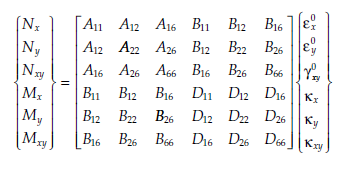in partion form : 


$$N_x =44\;\textrm{Mpa}-\textrm{mm}\;,\;\;\;N_y =44\;\textrm{Mpa}-\textrm{mm}\;,\;\;\;N_{\textrm{xy}} =44\;\textrm{Mpa}-\textrm{mm}\;\;$$


N=


 N = [0.050; 0 ;0]   % % force per unit length in Gpa-mm.....where (GPa mm)−1 = 10−3 (MPa mm)−1.

N =     0.0500
         0
         0


vpa(N,4)

$$ans = \left(\begin{array}{c} 0.05\\ 0\\ 0 \end{array}\right)$$

M=

 M = [0; 0; 0];  % Gpa-mm^2
% vpa(M,4)

midplane strain $\left(\varepsilon^o \right)$ & curvature $\left(\kappa \right)$:

k= [0; 0; 0]   % mm^-1 ...curvature

k =      0
     0
     0


e0= inv(A)*N-inv(A)*B*k  % mm/mm ....midplane strain

e0 =     0.0021
   -0.0015
         0


**Lamina Stresses and Strains **of kth ply at z distance from midplane: 

% to find stress in each laminae
F11 = 1/(Xt*Xc); % Tsai-wu strength coefficients
F1 = 1/Xt-1/Xc;
F22 = 1/(Yt*Yc);
F2 = 1/Yt-1/Yc;
F66 = 1/S^2;
F12 = -sqrt(F11*F22)/2;
fprintf('Tsai-Wu failure criteria for safe design is Tsai<=1')

Tsai-Wu failure criteria is Tsai<=1


for i = 1:length(theta)
    c = cosd(theta(i));
    s = sind(theta(i));
    T = [c^2 s^2 2*s*c; s^2 c^2 -2*s*c; -s*c s*c c^2-s^2]; % stress transformation matrix
    
    Q_11 = Q11*c^4+Q22*s^4+2*(Q12+2*Q66)*s^2*c^2;    %      Q_bar
    Q_12 = (Q11+Q22-4*Q66)*s^2*c^2+Q12*(c^4+s^4);
    Q_22 = Q11*s^4+Q22*c^4+2*(Q12+2*Q66)*s^2*c^2;
    Q_16 = (Q11-Q12-2*Q66)*c^3*s-(Q22-Q12-2*Q66)*c*s^3;
    Q_26 = (Q11-Q12-2*Q66)*c*s^3-(Q22-Q12-2*Q66)*c^3*s;
    Q_66 = (Q11+Q22-2*Q12-2*Q66)*s^2*c^2+Q66*(s^4+c^4);
    Q_k = [Q_11 Q_12 Q_16; Q_12 Q_22 Q_26; Q_16 Q_26 Q_66] ;% transformed lamina stiffness of kth layer
   
     fprintf('Stress at top surface of lamina %d, at z=%0.2f mm is =',i,z(i))
    sigma_top = Q_k*(e0 + z(i)*k )*1000 % stresses(bcs-x,y,z) at top of top surface of the kth layer (MPa)
    ss_top = T*sigma_top ; % stress (mcs-1,2,6)at top of top surface of the kth layer (Pa)
   
    Tsai_top = TsaiWu(ss_top,F11,F1,F22,F2,F66,F12);
    fprintf('Tsai at top surface of laminae %d is %d',i,Tsai_top)
    
    fprintf('Stress at bottom surface of lamina %d, at z=%0.2f mm is =',i,z(i))
    sigma_bottom = Q_k*(e0 + z(i+1)*k )*1000  % stresses at top of bottom surface of the kth layer (MPa)
    ss_bottom = T*sigma_bottom ;% stress (mcs)at top of bottom surface of the kth layer (Pa)
    Tsai_bottom = TsaiWu(ss_bottom,F11,F1,F22,F2,F66,F12);
    fprintf('Tsai at bottom surface of  %d th laminae is %d',i,Tsai_bottom)
    
    if (Tsai_top<1) && (Tsai_bottom<1)
        fprintf('Laminae is safe proceed further\n')
    else
        disp('Laminae failed')
        break
        
    end
    

end

Stress at top surface of lamina 1, at z=-0.50 mm is =

sigma_top =    50.0000
         0
   21.1614


Tsai at top surface of laminae 1 is 2.167786e-01

Stress at bottom surface of lamina 1, at z=-0.50 mm is =

sigma_bottom =    50.0000
         0
   21.1614


Tsai at bottom surface of  1 th laminae is 2.167786e-01

Laminae is safe proceed further


Stress at top surface of lamina 2, at z=-0.25 mm is =

sigma_top =    50.0000
         0
  -21.1614


Tsai at top surface of laminae 2 is 2.167786e-01

Stress at bottom surface of lamina 2, at z=-0.25 mm is =

sigma_bottom =    50.0000
         0
  -21.1614


Tsai at bottom surface of  2 th laminae is 2.167786e-01

Laminae is safe proceed further


Stress at top surface of lamina 3, at z=0.00 mm is =

sigma_top =    50.0000
         0
  -21.1614


Tsai at top surface of laminae 3 is 2.167786e-01

Stress at bottom surface of lamina 3, at z=0.00 mm is =

sigma_bottom =    50.0000
         0
  -21.1614


Tsai at bottom surface of  3 th laminae is 2.167786e-01

Laminae is safe proceed further


Stress at top surface of lamina 4, at z=0.25 mm is =

sigma_top =    50.0000
         0
   21.1614


Tsai at top surface of laminae 4 is 2.167786e-01

Stress at bottom surface of lamina 4, at z=0.25 mm is =

sigma_bottom =    50.0000
         0
   21.1614


Tsai at bottom surface of  4 th laminae is 2.167786e-01

Laminae is safe proceed further


function [Tsai,b] = TsaiWu(sigma,F11,F1,F22,F2,F66,F12)

s1 = sigma(1);
s2 = sigma(2);
tau1 = sigma(3);
%   Tsai-wu failure criteria
Tsai = F11*s1^2+F22*s2^2+F66*tau1^2+F1*s1+F2*s2+2*F12*s1*s2;

end

